clear
clc

a = 0;
b = 3;
intervalo = 128;
tol = 100;
maxiter = 10;
[x1,y1] = Euler('funcion',a,b,intervalo,1,tol,maxiter);
[x2,y2] = Euler('funcion',a,b,2*intervalo,1,tol,maxiter);

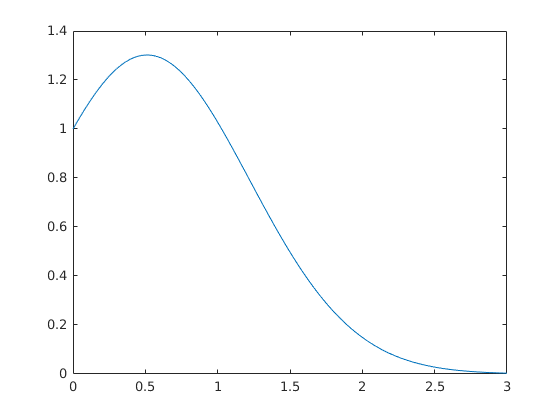

%%% graficar solucion
plot(x1,y1)

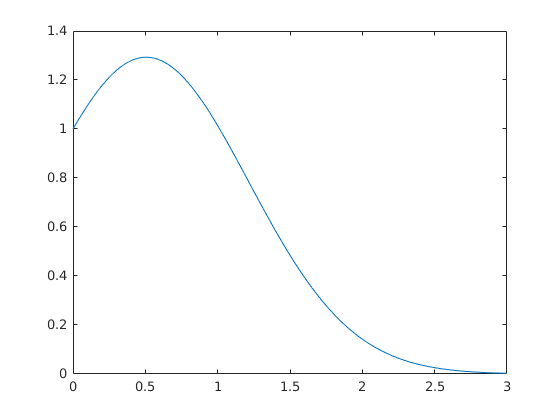

plot(x2,y2)

%%% calculo de error con N=8
solex1 = exp(1/4-(1/2-x1).^2);
error8 = abs(y1-solex1);
%plot(error8) 
%%% Valor maximo del error
error8 = max(error8)

error8 = 0.0283

%%% calculo de error con N=16
solex2 = exp(1/4-(1/2-x2).^2);
error16 = abs(y2-solex2);
%plot(error8) 
%%% Valor maximo del error
error16 = max(error16)

error16 = 0.0141

%%% orden del metodo 2^1 = 2
error8/error16

ans = 2.0131